% Using Imfindcircles
clear all; clc; close  all;
img = imread("cam_test.jpg");
img = im2gray(img);
F = fspecial("average",3);
img = imfilter(img,F);
BW = imbinarize(img,0.656);
se = strel(5);
e = edge(BW,'sobel');
[centers, radii] = imfindcircles(img,[1 30],"ObjectPolarity","bright")

centers =   577.4977  175.4902
  666.0485   91.5364
  667.2611   48.7554
  580.5500   47.7776
  128.5541   43.4620
  578.5128  133.5498
  310.9315   45.6668
  665.5101  131.4662
  222.5760   45.4670
  488.4665  173.9606


radii =    13.5818
   13.4854
   13.4382
   13.4976
   12.8830
   13.7211
   12.9419
   10.3744
   13.0488
   13.0975


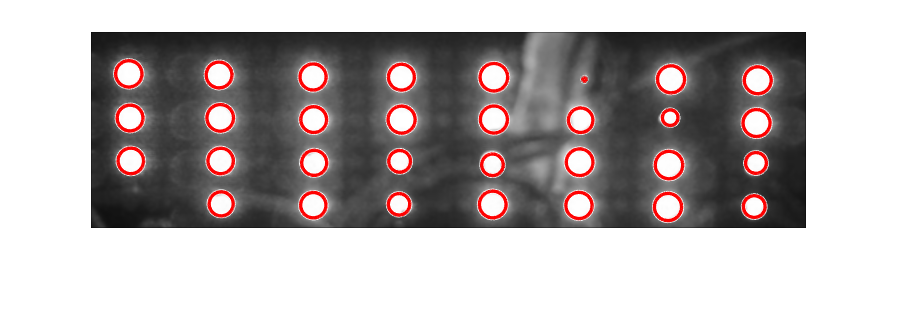

imshow(img)
viscircles(centers,radii);

% montage({img,BW, e});

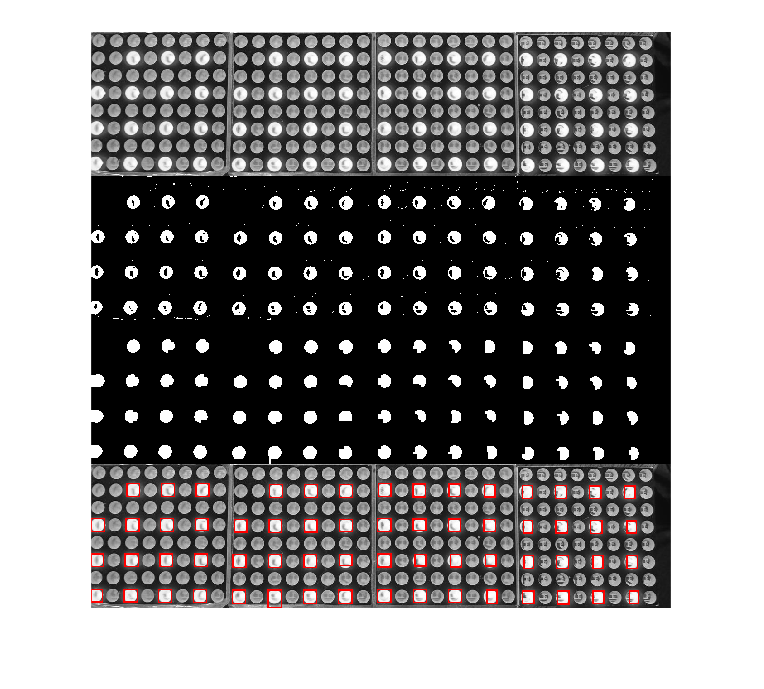

% dilation erosion
clear all; close all; clc;
img = imread("test.jpg");
img = rgb2gray(img);
BW = imbinarize(img,0.8);
SE = strel('square',5);
BWopen = imerode(BW,SE);
BWopen = imdilate(BWopen,SE);

SE = strel('square',15);
BWclose = imdilate(BWopen,SE);
BWclose = imerode(BWclose,SE);
props = regionprops("table",BWclose,"BoundingBox");
box = insertShape(img,"Rectangle",props.BoundingBox,'color','red','linew',3);
montage({img,BW,BWclose,box})

clear all; close all; clearvars;